%clear
% Specify the file path of the multi-page TIFF
%test JC
tic
% file_path = '/Users/platel/Desktop/exp/Sofia/ani55/mc_concat_reca_940_92um-001-_grid_13_factor.tif';
% path='/Users/platel/Desktop/exp/Sofia/ani55/';

% path='/Users/platel/Library/CloudStorage/GoogleDrive-jcplatel@gmail.com/Mon Drive/barrel/sofia/P0-P1/emx1/ani19_2022-01-21_b/';
% name='mot_corr_concat_downs_5.74_10_um.tif';
% filename="E:\backup_various\sofia\best_data_mc_downsampled\P2_P3_P4\emx1\ani31_2022-03-31_b_mc_tiff_downs_12.19_10_umtif.tif";
filename="E:\backup_various\sofia\best_data_mc_downsampled\P2_P3_P4\emx1\ani18_2022-01-21_b_mc_tiff_5.74_10_umtif.tif";
%load data and create analysis folder
%file_path='/Users/platel/Desktop/exp/Sofia/mc_tiff_downs_6.5_10_um.tif';
%path='/Users/platel/Desktop/exp/Sofia/';
% name='mc_tiff_downs_6.5_10_um.tif';
name='ani18_2022-01-21_b';
% PathSave='/Users/platel/Desktop/exp/analysis/';

PathSave='E:\backup_various\sofia\analysisJC';
% filename=[path name];
daytime = datestr(now,'yy_mm_dd_HH_MM_SS');
namefull=[PathSave daytime name '/'];
mkdir (namefull)    % make folder for saving analysis
% disp(['make new folder ' namefull])


% Read the multi-TIFF
info = imfinfo(filename);  % Get TIFF file information
num_pages = numel(info);    % Get the number of pages
height=info.Height;
width=info.Width;
size_pixel=10;
frame_rate=5;

image_data = cell(1, num_pages);
F=zeros(height,width,num_pages);

% Read each page of the TIFF
for page = 1:num_pages
    F(:,:,page)=imread(filename, 'Index', page);
end


%crop image
crop_pixel=2;
[width, height,nt]=size (F);
% intensity=intensity(1+crop_pixel:width-crop_pixel,1+crop_pixel:height-crop_pixel,:);
% [width, height,nt]=size (intensity);
NCell=width*height;
F=double(reshape(F(:,:,:),NCell,nt));
% F=double(F);


%Fluo=double(reshape(intensity,6241,18000));
% F=F./median(F,2);
% speed =smoothdata(speed,'gaussian',50);

%bleaching correction
for k = 1:NCell
    F(k, :) = detrend(F(k,:),'Continuous',false);
end
% disp('bleaching correction')
%traces=Fluo;
% Savitzky-Golay filter
F = sgolayfilt(F',3,5)';
F=normalize(F,2,"zscore");
%needs to be shifted____==
% intensity=cell2mat(image_data);


%test seqNMF
% Fr=double(F./median(F,2));
% Fr = sgolayfilt(Fr',3,7)';
% K = 10;
% L = 50;
% lambda =.005;
% [W, H, cost,loadings,power] = seqNMF(Tr1b,K,L,lambda)

% 
% plot (Fluo(100,:))
% hold on
% plot (traces(100,:))
% hold off

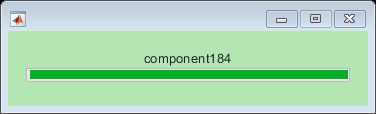

%approximation error to find number of K
tic
h = waitbar(0, 'Calculating Progress...','Color', [0.7 0.9 0.7]);
num_iterations=5;
ranks = 4:20:200;
options = statset('UseParallel', true,'MaxIter',1000);

% Calculate approximation error for each rank
tic
errors = zeros(size(ranks));
for i = 1:length(ranks)
    [Wtemp,H,errors(i)] = nnmf(F, ranks(i), 'algorithm', 'als','replicates', num_iterations, 'options', options);
    % errors(i) = norm(F - Wtemp*H, 'fro')^2; % Frobenius norm (=euclidian norm)
    
    % Reconstruct the matrix
    % F_reconstructed = Wtemp * H; 
    % % Calculate the Frobenius norm of the residual 
    % residual = F - F_reconstructed; 
    % frobenius_norm(i) = norm(residual, 'fro');
    progress = i / (length(ranks));
    waitbar(progress, h, ['component' num2str(ranks(i))]);
end

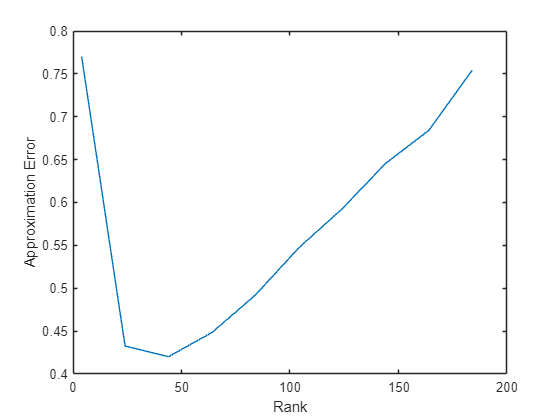


% Plot the approximation error
figure
plot(ranks, errors);
xlabel('Rank');
ylabel('Approximation Error');

% figure
% plot(ranks, frobenius_norm);
% xlabel('Rank');
% ylabel('Approximation Error');


[~ , a]=min(errors);
num_components=ranks(a);
toc

Elapsed time is 557.220631 seconds.


% Set parameters
tic
analysis_type='NMF_pixel';
% num_components = 10;  % number of components to extract
num_iterations = 100;  % number of iterations for the NMF algorithm

% Perform NMF
options = statset('UseParallel', true,'MaxIter',100);

[W, H , D] = nnmf(F, num_components, 'algorithm', 'als', 'replicates', num_iterations, 'options', options);
toc

% Plot the NMF components
figure;

for i = 1:num_components

    subplot(num_components,1,i)
    % set(gcf,'position',[0,0,1200,200])
    bar(W(:,i));
    %title(['NMF Component ', num2str(i)]);
    axis ([0 NCell 0 max(W(:,1))])
    box off

    set(gca, 'XTickLabel', []);

end
exportgraphics(gcf,[namefull 'NMFcomponents.png'],'Resolution',300);

% Plot the temporal activation of the NMF components
figure;

for i = 1:num_components

    subplot(num_components,1,i)
    %set(gcf,'position',[0,0,1000,200]);
    th(i)= 2*std(H(i,:)) ;
    [amplitude,locs] = findpeaks(H(i,:),'MinPeakProminence',th(i));
    SCE{i}=locs;
    plot(H(i,:));
    %title(['NMF Component ', num2str(i)]);
    %axis ([0 306 -0.04 0.5]);
    box off;
    set(gca, 'XTickLabel', []);
    % f=gcf;
    x=SCE{:,i};
    text(x,repmat(0.1,1,numel(x)),'*',"FontSize",8,"Color",'r')
    freq_SCE(i)=numel(amplitude)/nt*frame_rate;
    yline(th(i),'--')
end

mean_freq_SCE=mean(freq_SCE);
exportgraphics(gcf,[namefull 'temporalcomponents.png'],'Resolution',300);

% 
% % measure frequency per component
% freq_SCE=[];
% for i=1:num_components    
% 
%     th(i)= 2*std(H(i,:)) ;
% 
%     [amplitude,locs] = findpeaks(H(i,:),'MinPeakProminence',th(i));
%     SCE{i}=locs;
%     % [amplitude,locs] = findpeaks(Tr1b(i,:),'MinPeakHeight',th(i),'MinPeakDistance',MinPeakDistance);
%     % valeurs_identiques = intersect (locs,WinActive);
%     % locs_sans_ide=setdiff(locs(:), valeurs_identiques);
%     % Acttmp2{i}=locs_sans_ide;%%%%%%%%findchangepts(y,MaxNumChanges=10,Statistic="rms")
%     % %Acttmp2{i}=locs;
%     % ampli{i}=amplitude;
%     freq_SCE(i)=numel(amplitude)/nt*frame_rate;
% end
% mean_freq_SCE=mean(freq_SCE);

%make real image of components

for n=1:num_components

    image_component(n,:,:)=reshape(W(:,n),width,height);

end

figure;
i=0;
im=squeeze(image_component(1,:,:));
level = graythresh(im);
% props=struct('Area',[], 'Centroid',[], 'PixelList',[]);
props=struct('Area',[], 'Centroid',[], 'PixelList',[]);
region= repmat(props, 5, num_components);

for n=1:num_components
    i=i+1;
    set(gcf,'position',[0,0,1200,3000]);
    subplot(num_components,3,i)
    
    im=squeeze(image_component(n,:,:));
    imagesc(im)
    axis off
     %clim ([0 0.2]) 
    axis tight

    i=i+1;
    subplot(num_components,3,i)
    im=imgaussfilt(im,1); %gaussian filter
    imagesc(im)
    axis tight
    axis off
    % clim ([0 0.2]) 

    %thresholding
    %level = graythresh(im)
    levelstd = std2(im);
    % level=0.01;
    BW = imbinarize(im,levelstd);
    %radius = 50;
    se = strel('disk', 2);
    % se = offsetstrel('ball',5,5);
    BW = imerode(BW,se);
    BW = imdilate(BW,se);
    BW = imclose(BW,se);

    i=i+1;
    subplot(num_components,3,i)
    imagesc(BW)
    axis tight
    axis off
    % clim ([0 1]) 
    f=gcf;

    labeledImage = bwlabel(BW);

    numObjects(n) = max(labeledImage(:));
    % boundaries(n) = bwboundaries(labeledImage);
    region(1:numObjects(n),n)=regionprops(labeledImage, {'Area', 'Centroid', 'PixelList'});
    %props(n,numObjects(n)) = regionprops(labeledImage, {'Area', 'Centroid', 'PixelList'});
    % if numObjects(n) >0 && numObjects(n) <2 
    %     props(n) = regionprops(labeledImage, {'Area', 'Centroid', 'PixelList'});
    % end
end

exportgraphics(gcf,[namefull 'spatialNMF.png'],'Resolution',300);

 % write color code
 colors = [
    1 0 0;     % Red
    0 1 0;     % Green
    0 0 1;     % Blue
    1 1 0;     % Yellow
    1 0 1;     % Magenta
    0 1 1;     % Cyan
    0.5 0 0;   % Maroon
    0 0.5 0;   % Olive
    0 0 0.5;   % Navy
    0.5 0.5 0; % Olive Green
    0.5 0 0.5; % Purple
    0 0.5 0.5; % Teal
    0.75 0 0;  % Dark Red
    0 0.75 0;  % Lime Green
    0 0 0.75;  % Dark Blue
    0.75 0.75 0; % Dark Yellow
    0.75 0 0.75; % Dark Magenta
    0 0.75 0.75; % Dark Cyan
];

figure
black=zeros(width, height);
image(black)
colormap ("gray")
axis image
axis off
% i=0;
for n = 1:num_components %numel(props)

    % if isempty(props(n).PixelList)
    %     continue
    % end
    % pixelList = props(n).PixelList;
    for m=1 : numObjects(n)
        pixelList = region(m,n).PixelList;
        x = pixelList(:, 1);
        y = pixelList(:, 2);
        sorted_indices = convhull(x, y); 
        x = x(sorted_indices);
        y = y(sorted_indices);
    
        % Plot the contour
    
        hold on;
        % patch(x, y, colors(n,:), 'FaceAlpha', 0.1,'EdgeColor',colors(n,:));  
        patch(x, y,colors(n,:), 'EdgeColor',colors(n,:),'FaceColor','none','LineWidth',2)
        % i=i+1;
        % fid=fopen([namefull,'ROI' num2str(i) '.txt'],'w');
        % for o = 1:size(coor, 1)
        %     fprintf(fid, '%d %d\n', coor(o, 1), coor(o, 2));
        % end
        % fclose(fid);
    end
end
hold off
exportgraphics(gcf,[namefull 'patches.png'],'Resolution',300);


i=0;
test=repmat(intensity(:,:,1),1,1,3);
for n = 1:num_components %numel(props)
    for m=1 : numObjects(n)
        i=i+1;
        pixelList = region(m,n).PixelList;
        x = pixelList(:, 1);
        y = pixelList(:, 2);
        sorted_indices = convhull(x, y); 
        xcoo{i} = x(sorted_indices);
        ycoo{i} = y(sorted_indices);
    end
end

% Check the minimum and maximum values in the original image
minValue = min(intensity,[],"all");
maxValue = max(intensity,[],"all");

% Calculate the scaling factor to map the 16-bit range to the 8-bit range
scalingFactor = 255 / (maxValue - minValue);

% Apply the scaling factor and convert to 8-bit
intensity_corrected = uint8((intensity - minValue) * scalingFactor);


% tic
% % figure
% % %black=zeros(width, height);
% % image(black)
% % colormap ("gray")
% % axis image
% % clim ([min(intensity,[],'all') max(intensity,[],'all')] )
% f = figure('visible','off');
% colormap ("gray")
% axis off
% axis image
% min_int=min(intensity_corrected,[],'all');
% max_int=max(intensity_corrected,[],'all');
% 
% for n=1:2:nt
% 
%     %figure
%     image(intensity_corrected(:,:,n))
%     % clim ([min(intensity,[],'all') max(intensity,[],'all')] )
%     clim ([min_int max_int] )
%     % colormap ("gray")
%     axis off
%     axis image
%     for m=1:numel(xcoo)
%         % test(cell2mat(xcoo(m)), cell2mat(ycoo(m)),:)=colors(m,:)
%         hold on;
%         x=cell2mat(xcoo(m));
%         y=cell2mat(ycoo(m));
%         % patch(x, y, colors(m,:), 'FaceAlpha', 0.5);
%         patch(x, y,colors(m,:), 'EdgeColor',colors(m,:),'FaceColor','none','LineWidth',2)
%     end
%     hold off
%     frame = getframe(gcf);
%     imageData = frame2im(frame);
%     % filename = fullfile(namefull, sprintf('image_%03d.tif', n));
%     % imwrite(imageData, [namefull 'movie.tif'],'WriteMode', 'append', 'Compression', 'none');
%     % imwrite(imageData, filename);
%     imwrite(imageData, [namefull 'movie.tif'],'WriteMode', 'append',Compression='lzw')
% end
% 
% toc

tic
% Define the output video file name
outputVideoFile = 'output_video.mp4';

% Create a VideoWriter object with the desired settings
% Specify the file name, codec, frame rate, and optional quality
videoWriterObj = VideoWriter([namefull 'movie.mp4'], 'MPEG-4');
videoWriterObj.FrameRate = frame_rate*10;  % Frames per second (adjust as needed)
videoWriterObj.Quality = 90;    % Optional: Set video quality (0-100)

% Open the VideoWriter object for writing
open(videoWriterObj);

% Create a figure for displaying the animation (optional)
%figure;
f = figure('visible','off');
f = figure('visible','off');
colormap ("gray")
axis off
axis image
% min_int=min(intensity_corrected,[],'all');
% max_int=max(intensity_corrected,[],'all');
min_int=0;
max_int=10;
for n = 1:2:nt
    image(intensity_corrected(:,:,n))
    clim ([min_int max_int] )
    % colormap ("gray")
    axis off
    axis image
    for m=1:numel(xcoo)
        hold on;
        x=cell2mat(xcoo(m));
        y=cell2mat(ycoo(m));
        % patch(x, y, colors(m,:), 'FaceAlpha', 0.5);
        patch(x, y,colors(m,:), 'EdgeColor',colors(m,:),'FaceColor','none','LineWidth',2)
    end
    hold off
    frame = getframe(gcf);
    imageData = frame2im(frame);
    
    % Write the frame to the video
    writeVideo(videoWriterObj, imageData);
end

% Close the VideoWriter object to finish writing
close(videoWriterObj);

% Close the figure (optional)
close;

% Display a message indicating the video has been saved
disp(['Video saved ']);
toc

% tic
% % Define the output video file name
% outputVideoFile = 'output_video.mp4';
% 
% % Create a VideoWriter object with the desired settings
% % Specify the file name, codec, frame rate, and optional quality
% videoWriterObj = VideoWriter([namefull 'movie.mp4'], 'MPEG-4');
% videoWriterObj.FrameRate = frame_rate*10;  % Frames per second (adjust as needed)
% videoWriterObj.Quality = 90;    % Optional: Set video quality (0-100)
% 
% % Open the VideoWriter object for writing
% open(videoWriterObj);
% 
% % Create a figure for displaying the animation (optional)
% %figure;
% f = figure('visible','off');
% f = figure('visible','off');
% colormap ("gray")
% axis off
% axis image
% min_int=min(intensity_corrected,[],'all');
% max_int=max(intensity_corrected,[],'all');
% max_int=20;
% 
% for n = 1:nt
%     image(intensity_corrected(:,:,n))
%     clim ([min_int max_int] )
%     axis off
%     axis image
%     frame = getframe(gcf);
%     imageData(n,:,:,:) = frame2im(frame);
% end
% 
% for n = 1:5%num_components
% 
%     numimage=cell2mat(SCE(n))
% 
%     for m=numimage
%         f = figure('visible','off');
%         image(intensity_corrected(:,:,m))
%         % clim ([min_int max_int] )
%         axis off
%         axis image
%         hold on;
%         x=cell2mat(xcoo(n));
%         y=cell2mat(ycoo(n));
%         % patch(x, y, colors(m,:), 'FaceAlpha', 0.5);
%         patch(x, y,colors(n,:), 'EdgeColor',colors(n,:),'FaceColor','none','LineWidth',2)
%         hold off
%         frame = getframe(gcf);
%         imageData(m) = frame2im(frame);
%         close (gcf);
%     end  
% 
% end
% for n = 1:2:nt
%     writeVideo(videoWriterObj, imageData(n));
% end
% 
% % Close the VideoWriter object to finish writing
% close(videoWriterObj);
% 
% % Close the figure (optional)
% close;
% 
% % Display a message indicating the video has been saved
% disp(['Video saved ']);
% toc

% exportgraphics(gcf,[namefull 'patches.png'],'Resolution',300);
% exportgraphics(gcf,[namefull 'patches.png'],'Resolution',300);

% %export coordinates
% 
% i=0;
% 
% for n=1:num_components
% 
%     for m=1:numObjects(n)
%         i=i+1;
%         coo{i}=region(m,n).PixelList;
%         coor=cell2mat(coo(i));
%     end
%     fid=fopen([namefull,'ROI' num2str(i) '.txt'],'w');
%     for o = 1:size(coor, 1)
%         fprintf(fid, '%d %d\n', coor(o, 1), coor(o, 2));
%     end
%     fclose(fid);
% end

% 
% for i = 1:size(coo, 1)
%     fprintf(fid, '%d %d\n', coo(i, 1), coo(i, 2));
% end
% fprintf(fid, a);



% assembly_sofia


%calculation stat

area=zeros(num_components,1);
for n=1:num_components

    for m=1:numObjects(n)
        area(n)=region(m,n).Area+ area(n);
    end

    area(n)=area(n)/ numObjects(n)*size_pixel^2;
end
mean_area=mean(area);


%export in excel 

daytime = datestr(now,'yy_mm_dd_HH_MM_SS');
%first file in same folder as experiment
pathexcel=[namefull '/analysis.xlsx'];
%
numline=2;
writematrix('date',pathexcel,'Range','A1');
writematrix (daytime,pathexcel,'Range','A2');
writematrix ('nom',pathexcel,'Range','B1');
writematrix (name,pathexcel,'Range','B2');

writematrix ('analysis',pathexcel,'Range','C1');
writematrix (analysis_type,pathexcel,'Range',['C' num2str(numline)]);

writematrix ('num components',pathexcel,'Range','D1');
writematrix (num_components,pathexcel,'Range',['D' num2str(numline)]);
writematrix ('num iteration',pathexcel,'Range','E1');
writematrix (num_iterations,pathexcel,'Range',['E' num2str(numline)]);
writematrix ('size pixel',pathexcel,'Range','F1');
writematrix (size_pixel,pathexcel,'Range',['F' num2str(numline)]);
writematrix ('mean area component',pathexcel,'Range','G1');
writematrix (mean_area,pathexcel,'Range',['G' num2str(numline)]);
writematrix ('mean_freq_SCE', pathexcel,'Range','H1');
writematrix (mean_freq_SCE, pathexcel,'Range','H2');  

writematrix ('all area', pathexcel,'Range','I1');
writematrix ('freq_SCE/compo', pathexcel,'Range','J1');
for n=1:num_components
   writematrix (area(n), pathexcel,'Range',['I' num2str(n+1)]);
   writematrix (freq_SCE(n), pathexcel,'Range',['J' num2str(n+1)]);
end
% writematrix (num2str(allarea), pathexcel,'Range','H2');


%writematrix (num2str(freq_SCE), pathexcel,'Range','J2');

% writematrix ('cell/assembly',pathexcel,'Range','I1');
% writematrix (idortho,pathexcel,'Range',['I' num2str(numline)]);
% writematrix ('assemblyraw',pathexcel,'Range','J1');
% writematrix (writeassemblyraw,pathexcel,'Range',['J' num2str(numline)]);
% writematrix ('cell/assemblyraw',pathexcel,'Range','K1');
% writematrix (idraw,pathexcel,'Range',['K' num2str(numline)]);
% writematrix ('assemblystat',pathexcel,'Range','L1');
% writematrix (writeassemblystat,pathexcel,'Range',['L' num2str(numline)]);
% writematrix ('cell/assemblystat',pathexcel,'Range','M1');
% writematrix (idstat,pathexcel,'Range',['M' num2str(numline)]);
% writematrix ('sequences',pathexcel,'Range','N1');
% writematrix ('no seq yet',pathexcel,'Range',['N' num2str(numline)]);
% writematrix ('Ncell',pathexcel,'Range','O1');
% writematrix (NCell,pathexcel,'Range',['O' num2str(numline)]);
% writematrix ('frames',pathexcel,'Range','P1');
% writematrix (length(Tr1b),pathexcel,'Range',['P' num2str(numline)]);
% writematrix ('sampling rate',pathexcel,'Range','Q1');
% writematrix (sampling_rate,pathexcel,'Range',['Q' num2str(numline)]);
% writematrix ('nb frame not running',pathexcel,'Range','R1');
% writematrix (length(WinRest),pathexcel,'Range',['R' num2str(numline)]);
% writematrix ('average speed',pathexcel,'Range','S1');
% writematrix (average_speed,pathexcel,'Range',['S' num2str(numline)]);
% writematrix ('sce_n_cells_threshold',pathexcel,'Range','T1');
% writematrix (sce_n_cells_threshold,pathexcel,'Range',['T' num2str(numline)]);
% writematrix ('n_kmean_surrogate',pathexcel,'Range','U1');
% writematrix (kmeans_surrogate,pathexcel,'Range',['U' num2str(numline)]);
% writematrix ('min_sce_distance',pathexcel,'Range','V1');
% writematrix (MinPeakDistancesce,pathexcel,'Range',['V' num2str(numline)]);
% writematrix ('MinPeakDistance',pathexcel,'Range','W1');
% writematrix (MinPeakDistance,pathexcel,'Range',['W' num2str(numline)]);
% writematrix ('synchronous_frames',pathexcel,'Range','X1');
% writematrix (synchronous_frames,pathexcel,'Range',['X' num2str(numline)]);
% writematrix ('percentile sce threshold',pathexcel,'Range','Y1');
% writematrix (percentile,pathexcel,'Range',['Y' num2str(numline)]);
% writematrix ('mini threshold activity detection',pathexcel,'Range','Z1');
% writematrix (minithreshold,pathexcel,'Range',['Z' num2str(numline)]);



% %here we write all experiments
% 
% pathexcel=[PathSave 'analysis_sofia_ALL.xlsx'];
% data =readcell(pathexcel);
% [row , col]=size (data);
% numline=row+1;
% 
% writematrix (daytime,pathexcel,'Range',['A' num2str(numline)]);
% writematrix (name,pathexcel,'Range',['B' num2str(numline)]);
% writematrix (analysis_type,pathexcel,'Range',['C' num2str(numline)]);
% writematrix (num_components,pathexcel,'Range',['D' num2str(numline)]);
% writematrix (num_iterations,pathexcel,'Range',['E' num2str(numline)]);
% writematrix (size_pixel,pathexcel,'Range',['F' num2str(numline)]);
% writematrix (mean_area,pathexcel,'Range',['G' num2str(numline)]);
% writematrix (allarea,pathexcel,'Range',['H' num2str(numline)]);
% % 
% % writematrix (daytime,pathexcel,'Range',['A' num2str(numline)]);
% % writematrix (identifier,pathexcel,'Range',['B' num2str(numline)]);
% % writematrix (session,pathexcel,'Range',['C' num2str(numline)]);
% % writematrix (NRace,pathexcel,'Range',['D' num2str(numline)]);
% % writematrix (freqsce,pathexcel,'Range',['E' num2str(numline)]);
% % writematrix (NRaceOK,pathexcel,'Range',['F' num2str(numline)]);
% % writematrix (freqsceok,pathexcel,'Range',['G' num2str(numline)]);
% writematrix (writeassemblyortho,pathexcel,'Range',['H' num2str(numline)]);
% writematrix (num2str(idortho),pathexcel,'Range',['I' num2str(numline)]);
% writematrix (writeassemblyraw,pathexcel,'Range',['J' num2str(numline)]);
% writematrix (num2str(idraw),pathexcel,'Range',['K' num2str(numline)]);
% writematrix (writeassemblystat,pathexcel,'Range',['L' num2str(numline)]);
% writematrix (num2str(idstat),pathexcel,'Range',['M' num2str(numline)]);
% writematrix ('no seq yet',pathexcel,'Range',['N' num2str(numline)]);
% writematrix (NCell,pathexcel,'Range',['O' num2str(numline)]);
% writematrix (length(F),pathexcel,'Range',['P' num2str(numline)]);
% writematrix (sampling_rate,pathexcel,'Range',['Q' num2str(numline)]);
% writematrix (Nz,pathexcel,'Range',['R' num2str(numline)]);
% writematrix (average_speed,pathexcel,'Range',['S' num2str(numline)]);
% writematrix (sce_n_cells_threshold,pathexcel,'Range',['T' num2str(numline)]);
% writematrix (kmeans_surrogate,pathexcel,'Range',['U' num2str(numline)]);
% writematrix (MinPeakDistancesce,pathexcel,'Range',['V' num2str(numline)]);
% writematrix (MinPeakDistance,pathexcel,'Range',['W' num2str(numline)]);
% writematrix (synchronous_frames,pathexcel,'Range',['X' num2str(numline)]);
% writematrix (percentile,pathexcel,'Range',['Y' num2str(numline)]);
% writematrix ('mini threshold activity detection',pathexcel,'Range','Z1');
% writematrix (minithreshold,pathexcel,'Range',['Z' num2str(numline)]);

save([namefull,'analysis_results.mat'])  
toc

% % Define a range of ranks
% ranks = 6:15;
% num_iterations=10;
% tic
% % Calculate AIC(Akaike Information Criterion) and BIC(Bayesian Information Criterion) for each rank 
% aic_values = zeros(size(ranks));
% bic_values = zeros(size(ranks));
% for i = 1:length(ranks)
%     [W,H] = nnmf(F, ranks(i), 'algorithm', 'als','replicates', num_iterations, 'options', options);
%     rss = norm(F - W*H, 'fro')^2;
%     num_parameters = ranks(i)*size(F,2) + ranks(i)*size(F,1);
%     aic_values(i) = 2*num_parameters + size(F,1)*size(F,2)*log(rss/(size(F,1)*size(F,2)));
%     bic_values(i) = num_parameters*log(size(F,1)*size(F,2)) + size(F,1)*size(F,2)*log(rss/(size(F,1)*size(F,2)));
% end
% 
% % Plot AIC and BIC
% figure
% plot(ranks, aic_values, '-o');
% hold on;
% plot(ranks, bic_values, '-o');
% xlabel('Rank');
% ylabel('Information Criterion');
% legend('AIC', 'BIC');
% toc


%%%%%%cross validation%%%%%%%%%%% 
% Define the range of k values to test
% k_values = 1:20;  % Adjust the range as needed

% Specify the number of cross-validation folds
% num_folds = 5;    % You can change the number of folds
% % Initialize a cell array to store the cross-validation results
% cv_rmse = cell(length(k_values), num_folds);
% 
% % Perform k-fold cross-validation for each value of k
% for i = 1:length(k_values)
%     k = k_values(i);
% 
%     for fold = 1:num_folds
%         % Split your data into training and testing sets for this fold (e.g., using cvpartition or manually)
%         cv = cvpartition(size(F, 1), 'KFold', num_folds);
%         train_indices = training(cv, fold);
%         test_indices = test(cv, fold);
%         F_train = F(train_indices, :);
%         F_test = F(test_indices, :);
% 
%         % Perform NNMF on the training data with the current k
%         [W, H] = nnmf(F_train, k, 'options', options);
% 
%         % Reconstruct the test data with the same dimensions as F_test
%         F_test_reconstructed = W * H;
%         F_test_reconstructed = imresize(F_test_reconstructed, size(F_test));
% 
%         % Calculate RMSE for this fold
%         rmse = sqrt(mean((F_test - F_test_reconstructed).^2));
% 
%         % Store the RMSE in the cv_rmse cell array
%         cv_rmse{i, fold} = rmse;
%     end
% end
% 
% % Calculate the mean RMSE across all folds for each k
% mean_cv_rmse = zeros(length(k_values), 1);
% for i = 1:length(k_values)
%     rmse_values = cell2mat(cv_rmse(i, :)); % Convert cell array to matrix
%     mean_cv_rmse(i) = mean(rmse_values);
% end
% 
% % Find the optimal k (e.g., the one with the lowest mean RMSE)
% [optimal_k, idx] = min(mean_cv_rmse);
% 
% % Display the results
% fprintf('Optimal number of components (k) selected: %d\n', k_values(idx));

% return
% 
% nbassemblies=length(assemblyortho);
% n=1
% for n=1:nbassemblies
%    [subrow, subcol] = ind2sub([55, 55], assemblyortho{n}); 
% 
%    cellassembly{n,1} = subrow;
%    cellassembly{n,2} = subcol;
% end
% black=zeros(55,55)
% figure
% imagesc(black)
% colormap (gray)
% hold on

% for n=1:nbassemblies
%     x = cellassembly{n,1}; % X coordinates
%     y = cellassembly{n,2}; % Y coordinates
% 
%     % Combine x and y into a single matrix of points
%     points = [x', y'];
% 
%     % Find the convex hull of the points
%     k = convhull(points);
% 
%     % Sort the vertices in clockwise order
%     x_sorted = x(k);
%     y_sorted = y(k);
%     % plot (cellassembly{n,1},cellassembly{n,2},'.', 'MarkerSize', 30,"Color",colors(n,:))
%     patch (x_sorted,y_sorted,colors(n,:))
% end
% hold off
% % for n=2%:nbassemblies
% %     plot (cellassembly{n,1},cellassembly{n,2},'.', 'MarkerSize', 30,"Color",'r')
% % end
% % for n=3%:nbassemblies
% %     plot (cellassembly{n,1},cellassembly{n,2},'.', 'MarkerSize', 30,"Color",'g')
% % end


% figure
% imagesc(black)
% colormap (gray)
% hold on
% 
% for n=1:nbassemblies
% 
% 
%     plot (cellassembly{n,1},cellassembly{n,2},'.', 'MarkerSize', 30,"Color",colors(n,:))
% 
% end
% hold off

%measurement size assembly
% 
% for n=1:nbassemblies
% 
%    area_assembly(n)=length(assemblyortho{n})*size_pixel^2
% 
% end
% mean_area=mean(area_assembly)
% 